FM调制系统的软件实现

待处理信号

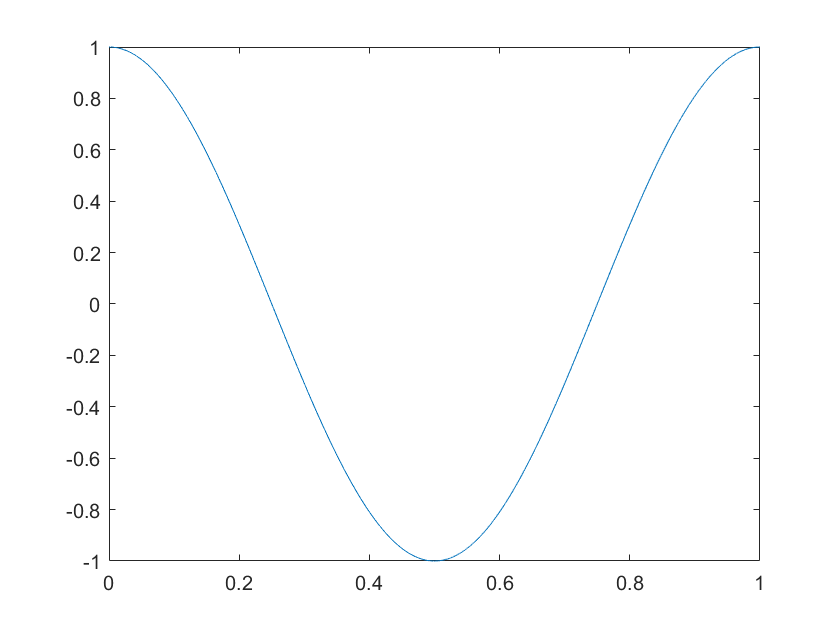

fs = 10000;
t = 0:1/fs:1;
message = cos(2*pi*t);
plot(t, message);

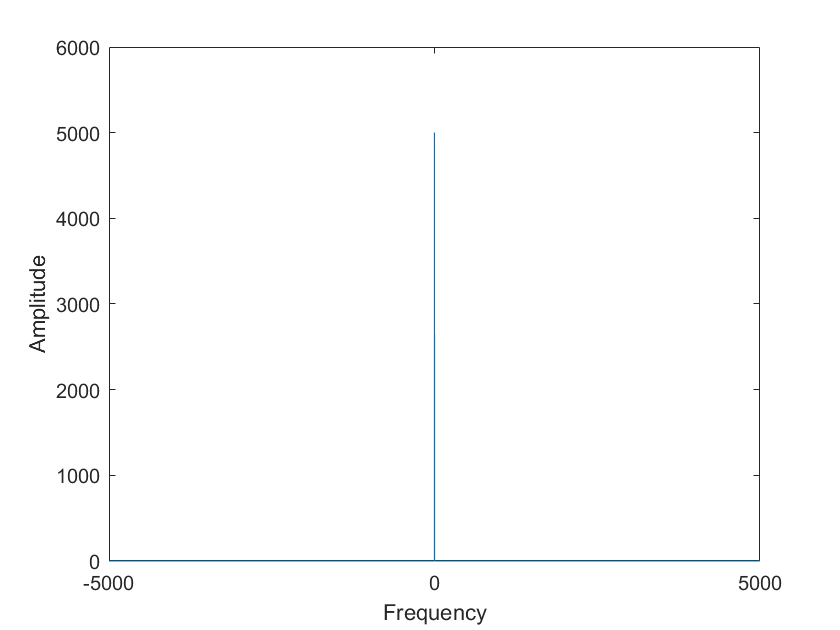

plotF(message, fs);

调制

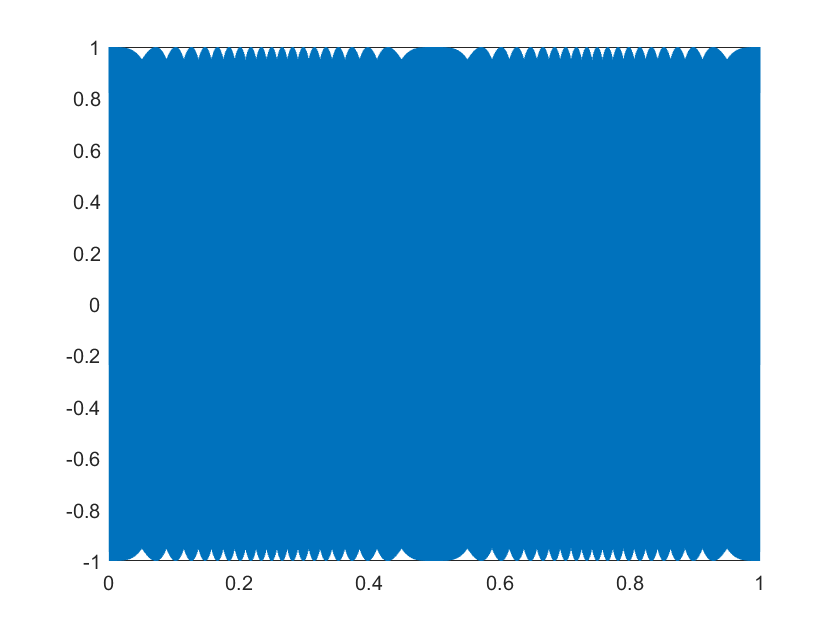

kf = 1;
Ac = 1;
modulated = Ac * cos(2*pi*1000*t + 2*pi*kf*message);
plot(t, modulated);

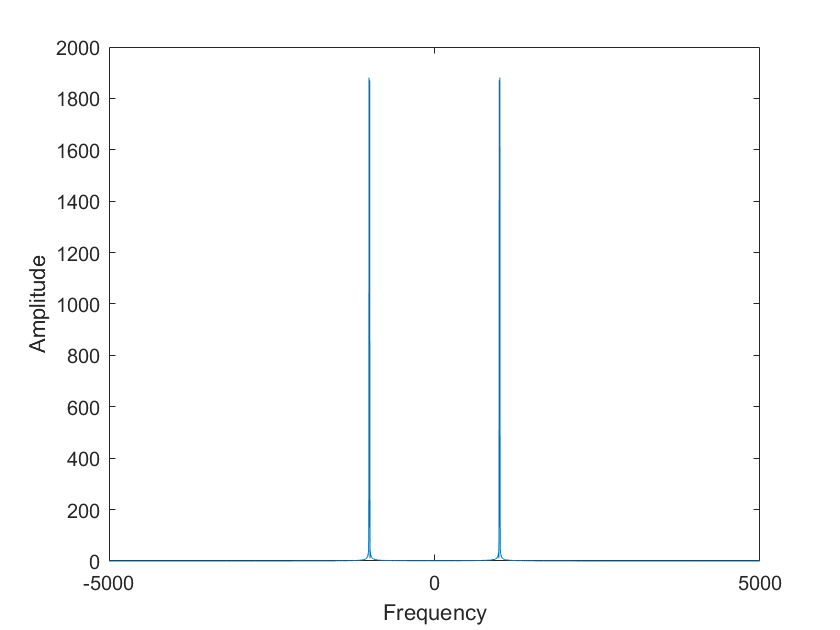

plotF(modulated, fs);

信道

sig_in_channel = modulated;

解调

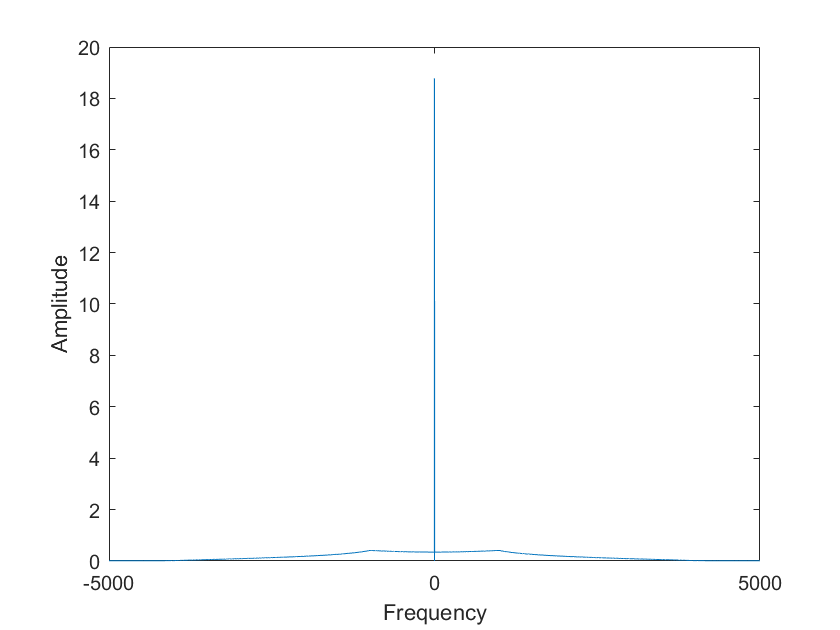

sig_dfm = [diff(sig_in_channel), 0];
sig_dfm_envelope = abs(hilbert(sig_dfm));
out = sig_dfm_envelope - mean(sig_dfm_envelope);
plotF(out, fs);